InstanciateIzhikevichNet;
mynet.sampling = false;
noise_window = 50; % in seconds
mynet.sigma_ex = 5;
mynet.sigma_inh = 2;

n_mems = 5;
for i=1:n_mems
    stim = Stimulation(mynet, 100, 2, 30, 50, 5);
    mynet.stimulation = true;
    mynet.stims = [stim];
    mynet.run(100000);
    mynet.stimulation = false;
    mynet.STDP = false;
    mynet.noise = true;
    mynet.run(noise_window*1000);
    mynet.STDP = true;
    mynet.noise = false;
end



data = mynet.getData();
firings = data.firings;


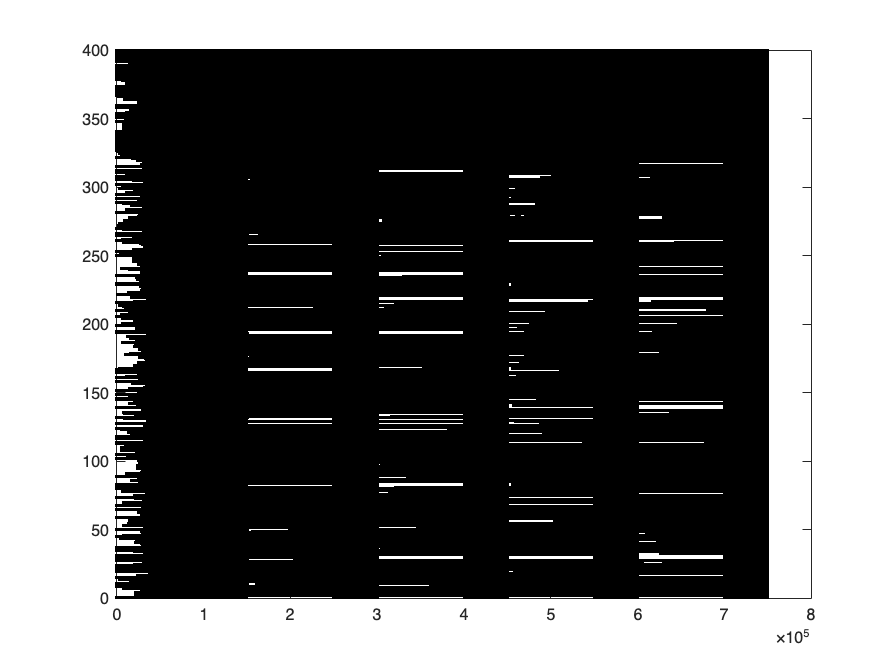

figure;
% index = (firings(1, :) < 200000) & (firings(1, :) > 199700);
% index = (firings(1, :) < 220000);
plot(firings(1, :), firings(2, :), 'k.')

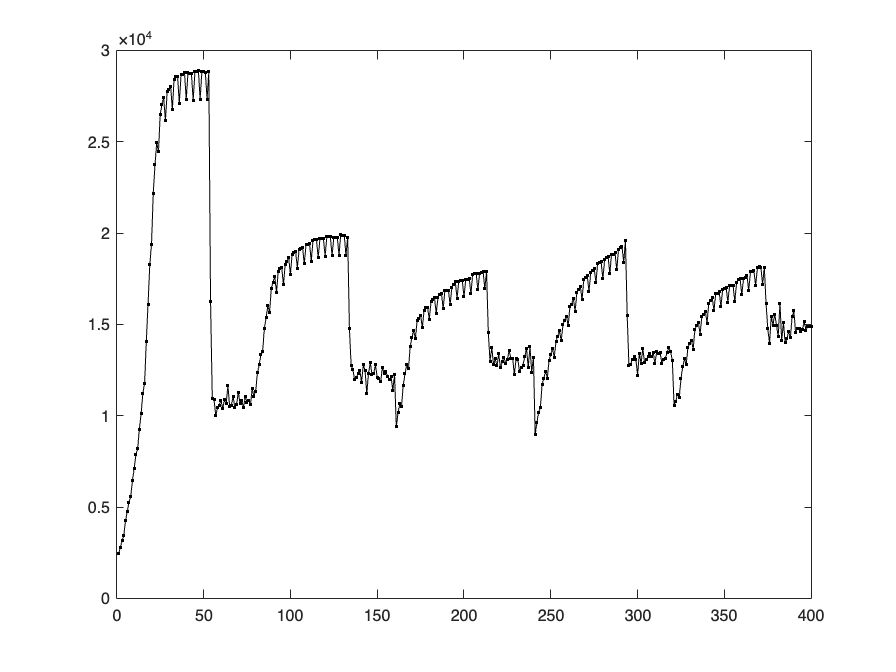

plot(histcounts(firings(1, :), 400), 'k.-')

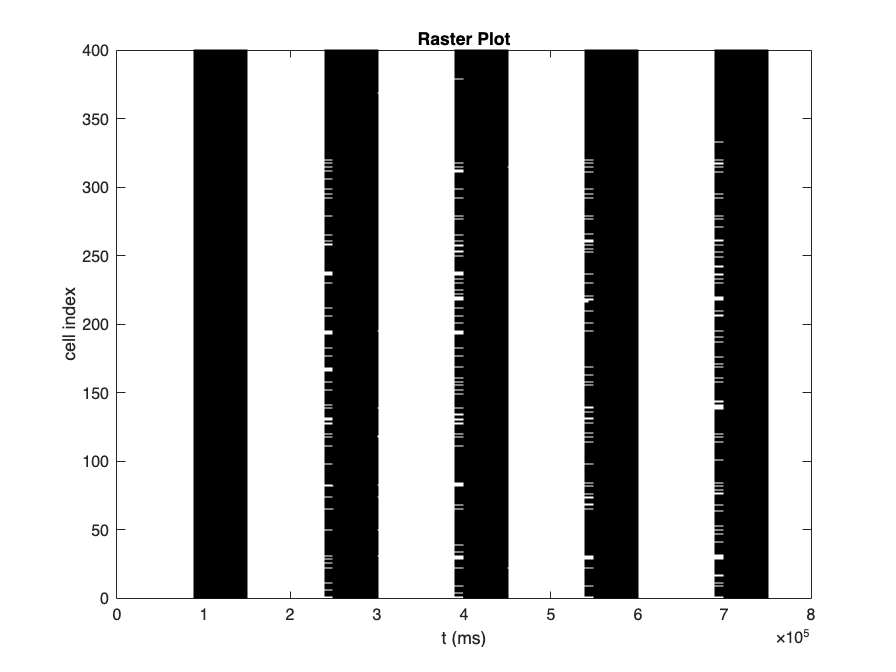

step = 100000 + noise_window*1000;

f = containers.Map();
for i = 1:n_mems
    index1 = (firings(1, :) > step*(i-1)+ 90000 ) & (firings(1, :) < step*(i-1)+100000);
    index2 = (firings(1, :) > step*(i-1)+100000 ) & (firings(1, :) < step*(i-1) + step);
    f(['mem', num2str(i)]) = firings(:, index1);
    f(['noise', num2str(i)]) = firings(:, index2);

end

figure();
ff = cell2mat(f.values());
plot(ff(1, :), ff(2, :), 'k.', MarkerSize=1)
xlabel("t (ms)")
ylabel("cell index")
title("Raster Plot")

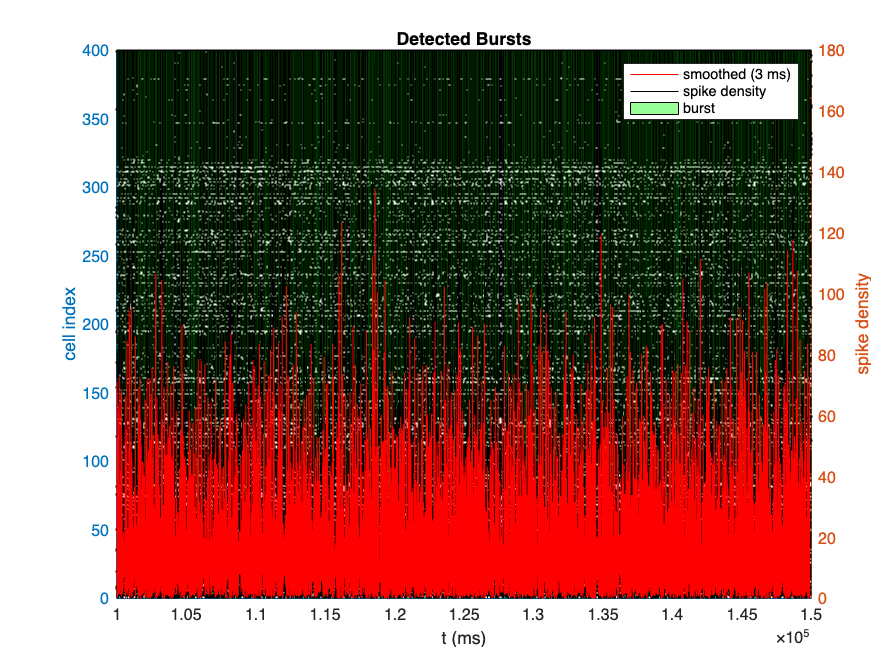

Detected bursts (start, end) in ms:
   1.0e+05 *

    1.0002    1.0003
    1.0006    1.0008
    1.0013    1.0014
    1.0017    1.0018
    1.0026    1.0027
    1.0029    1.0031
    1.0034    1.0035
    1.0038    1.0039
    1.0060    1.0061
    1.0065    1.0065
    1.0068    1.0070
    1.0073    1.0074
    1.0086    1.0087
    1.0090    1.0091
    1.0094    1.0095
    1.0099    1.0100
    1.0103    1.0105
    1.0108    1.0109
    1.0116    1.0117
    1.0128    1.0129
    1.0132    1.0134
    1.0137    1.0138
    1.0150    1.0151
    1.0153    1.0155
    1.0158    1.0159
    1.0162    1.0164
    1.0167    1.0168
    1.0171    1.0172
    1.0176    1.0177
    1.0181    1.0182
    1.0185    1.0186
    1.0189    1.0190
    1.0197    1.0197
    1.0200    1.0201
    1.0204    1.0205
    1.0213    1.0215
    1.0217    1.0218
    1.0222    1.0223
    1.0227    1.0228
    1.0232    1.0233
    1.0236    1.0237
    1.0240    1.0241
    1.0244    1.0245
    1.0248    1.0250
    1.0253    1.0254
    1

bursts = [];
num_burst = containers.Map(f.keys, f.values);
key_list = f.keys;
for key = key_list(6)
    [bursts_temp, fig] = BurstDetector(f(key{1}), [], true, 'All', 3, 3);
    
    bursts = [bursts; bursts_temp];
    num_burst(key{1}) = size(bursts_temp, 1);
end

% f = f(:, f(2, :) <= 320);
[features, f_names] = ExtractBurstFeatures(cell2mat(f.values()), bursts);

Burst Features (First Spike Times, Mean-Subtracted and NaN-Imputed):
    Neuron 1 First Spike Time    Neuron 2 First Spike Time    Neuron 3 First Spike Time    Neuron 4 First Spike Time    Neuron 5 First Spike Time    Neuron 6 First Spike Time    Neuron 7 First Spike Time    Neuron 8 First Spike Time    Neuron 9 First Spike Time    Neuron 10 First Spike Time    Neuron 11 First Spike Time    Neuron 12 First Spike Time    Neuron 13 First Spike Time    Neuron 14 First Spike Time    Neuron 15 First Spike Time    Neuron 16 First Spike Time    Neuron 17 First Spike Time    Neuron 18 First Spike Time    Neuron 19 First Spike Time    Neuron 20 First Spike Time


assemblies = features;
X_mean = nanmean(assemblies, 2);  
X_std = nanstd(assemblies, 0, 2); 

assemblies = (assemblies - X_mean) ./ X_std;

% assemblies = [assemblies(100, :); assemblies(200, :); assemblies(300, :); assemblies(301:end, :)];
% dist = squareform(pdist(assemblies, 'correlation'));
f = waitbar(0, "Please wait");
dist = zeros(size(assemblies, 1), size(assemblies, 1));
for i = 1:size(dist,1)
    waitbar((i-1)/size(dist, 1), f, "Please wait")
    for j = i:size(dist,2)
        idx = ~isnan(assemblies(i, :)) & ~isnan(assemblies(j, :));
        if sum(idx) > 50
            dist(i, j) = corr(assemblies(i, idx)', assemblies(j, idx)');
            dist(j, i) = dist(i, j);
        end
    end
end
close(f)

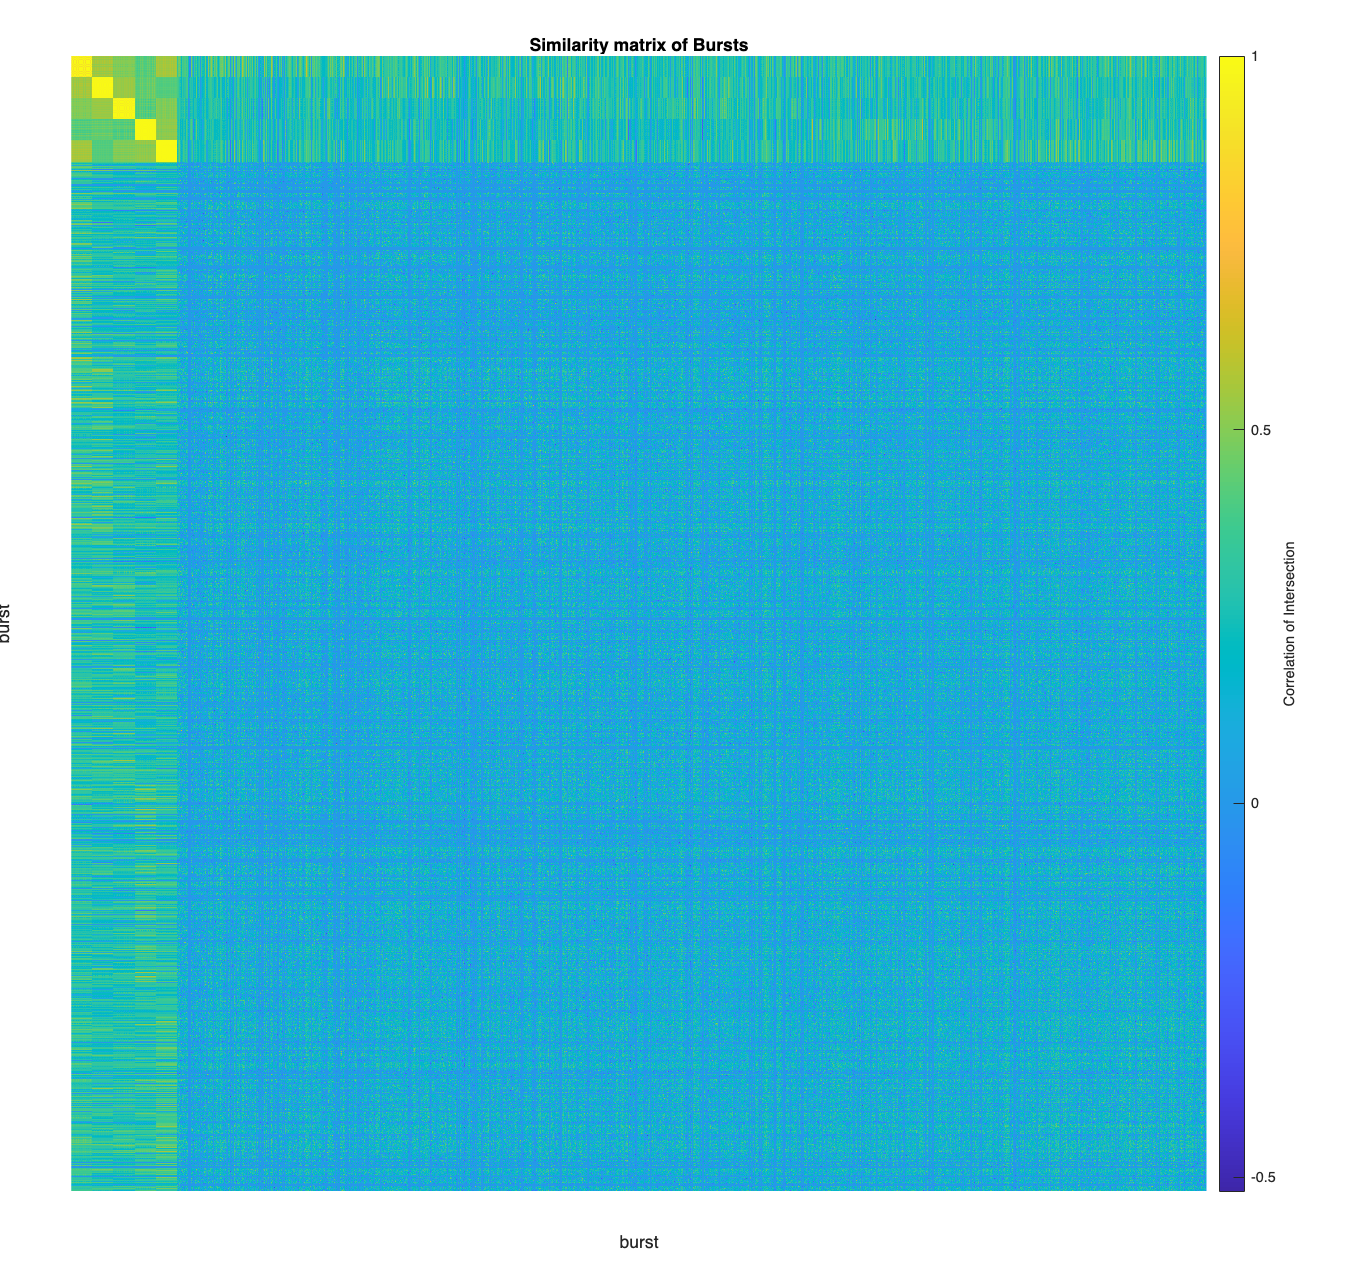

fig = figure(); fig.Position(3:4) = [800, 800]; 
imshow(dist);
colormap('parula');
cb = colorbar();
clim([min(dist, [], 'all'), max(dist, [], 'all')])
xlabel('burst'); ylabel('burst'); cb.Label.String = "Correlation of Intersection";
title("Similarity matrix of Bursts")
saveas(fig, ['Plots' filesep 'image3.png'])

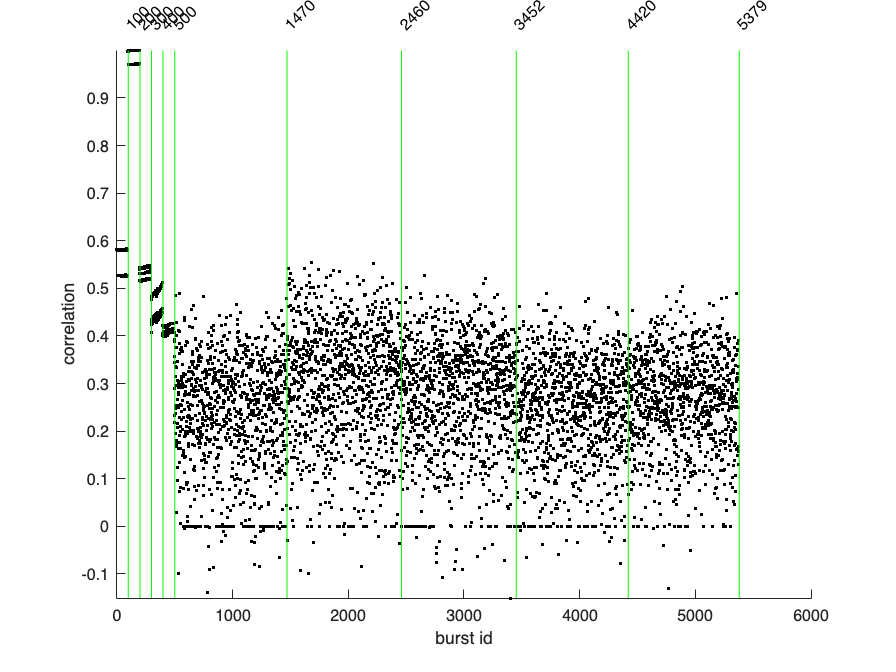


fig = figure(); hold on;
data = dist(200, (n_mems+1):end);
plot(data, 'k.')
counter= 0;
l = num_burst.values;
for b = l(1:end)
    counter = counter + b{1};
    plot(counter*[1, 1], [min(data), max(data)], 'g-')
    text(counter, 1.05*max(data), num2str(counter), "Rotation",45)
    % boxplot(assemblies)
end
ylim([min(data), max(data)])
xlabel("burst id")
ylabel("correlation")
saveas(fig, ['Plots' filesep 'image4.png'])

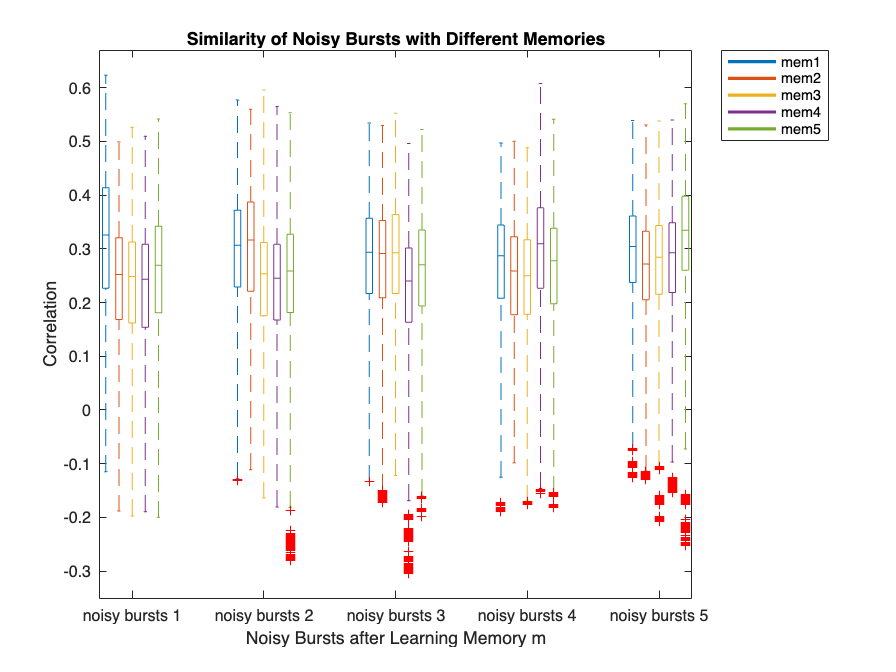


index = [];
n = 0;
for num = num_burst.values
    index = [index; [n + 1, num{1} + n]];
    n = num{1} + n;
end

% Initialize data as a cell array
data = cell(n_mems, n_mems);  
c_label = {};  % Category labels
g_label = {};  % Group labels

% Populate data and labels
for mem = 1:n_mems
    for i = 1:n_mems
        % Extract data for each (mem, i) combination
        temp = dist((mem - 1) * 100 + (1:100), index(i+n_mems, 1):index(i+n_mems, 2));
        
        % Store data in the cell array
        data{i, mem} = temp(:)';  % Ensure each group data is a row vector

        % Define labels
        if mem == 1
            c_label{i} = ['noisy bursts ', num2str(i)];
        end
        g_label{mem} = ['mem', num2str(mem)];
    end
end

% Call the function
fig = figure();
plotGroupedBox(data, c_label, g_label);
saveas(fig, ['Plots' filesep 'image5.png'])



function plotGroupedBox(data, category_labels, group_labels)
    % plotGroupedBox: Creates a box plot with closely grouped boxes for each category,
    % with distinct colors for each group and a legend.
    % 
    % Parameters:
    %   data - Cell array where each cell contains data for each group within categories.
    %          Each cell represents one group (a vector) for each category.
    %   category_labels - Cell array of strings for main categories
    %   group_labels - Cell array of strings for sub-group labels within each category

    % Check the dimensions of data and labels
    num_categories = length(category_labels);
    num_groups = length(group_labels);
    
    % Combine data into one vector and prepare grouping indices
    all_data = [];          % Concatenate all data
    positions = [];         % Custom x-axis positions
    categories = [];        % Main category grouping variable
    groups = [];            % Sub-group within each category

    % Define spacing for box positions
    offset = 0.1;           % Distance between boxes in the same category
    base_pos = 1;           % Starting position for the first category
    position_counter = base_pos;
    
    % Define colors for each group
    colors = lines(num_groups); % Use default MATLAB colormap 'lines' for distinct colors
    
    for c = 1:num_categories
        for g = 1:num_groups
            % Concatenate data for each group within each category
            group_data = data{c, g};
            all_data = [all_data; group_data(:)]; % Add group data
            
            % Set category and group labels for this group
            categories = [categories; repmat(c, length(group_data), 1)];
            groups = [groups; repmat(g, length(group_data), 1)];
            
            % Define x-axis position for each box plot group
            positions = [positions, position_counter + (g - (num_groups + 1) / 2) * offset];
        end
        % Increment position for the next category
        position_counter = position_counter + 1;
    end

    % Generate the box plot with custom positions
    h = boxplot(all_data, {categories, groups}, 'positions', positions, 'Labels', repmat(group_labels, 1, num_categories), 'Whisker', 2.5);

    % Set color for each group box
    for g = 1:num_groups
        set(h(:, g:num_groups:end), 'Color', colors(g, :));  % Apply color to each group
    end

    % Customize the x-axis to label only the main categories
    xticks(base_pos:num_categories);           % Place ticks at category centers
    xticklabels(category_labels);               % Assign labels to main categories
    xlabel('Noisy Bursts after Learning Memory m');
    ylabel('Correlation');
    title('Similarity of Noisy Bursts with Different Memories');

    % Add legend
    hold on;
    for g = 1:num_groups
        plot(NaN, NaN, 'Color', colors(g, :), 'LineWidth', 2);  % Dummy plots for legend colors
    end
    hold off;
    legend(group_labels, 'Location', 'bestoutside');
end




% [~, clusters, ~] = DimensionalityReductionPCA(features, 2, true, 4, f_names);
% figure; hold on;
% plot(clusters, 'ko')
% xlabel("burst id")
% ylabel("cluster id")
% counter = 0;
% 
% for key = num_burst.keys
%     s = key{1};
%     area([counter, counter + num_burst(s)], [4, 4], 'FaceAlpha', 0.3)
%     counter = counter + num_burst(s);
% end

% Select optimal number of clusters (K value) using specified range
fh = @(X,K)(kmeans(X,K,"Distance","cosine"));
eva = evalclusters(features,fh,"CalinskiHarabasz","KList",2:10);
clear fh
K = eva.OptimalK;
clusterIndices = eva.OptimalY;

% Display cluster evaluation criterion values
figure
bar(eva.InspectedK,eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - calinskiHarabaszCriterion");
legend("Optimal number of clusters is " + num2str(K))
title("Evaluation of Optimal Number of Clusters")
disp("Optimal number of clusters is " + num2str(K));
clear K eva

% Calculate centroids
transformedData = features./sqrt(sum(features.^2,2));
centroids = grpstats(transformedData,clusterIndices,"mean");
clear transformedData

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(features);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i2 = 1:numel(h)
    h(i2).DisplayName = strcat("Cluster",h(i2).DisplayName);
end
clear h i2 score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");